# Optimal Savings Choice in a 2 period Model with initial Wealth

## Model Components and Maximization Problem

Suppose we have a household who will have no income tomorrow, but has $b$ dollar income income today. He needs to determine how much to save.

If she saves $0$ today, she will die tomorrow due to hunger. If she saves all $b$ today, she will die of hunger today. Mathmatically, we could use log utility to describe this $0$ state of desperation. As consumption gets close to $0$, utility goes towards negative infinity, and utility is not defined at $0$.

We can write down the model where we maximize utility over choices $x_{today}, x_{tomorrow}$:

- **Utility**: $U(c_{today}, c_{tomrrow}) = \log(c_{today}) + 0.95 \cdot \log(c_{tomorrow})$

- **Budget Today**: $c_{today} + save = b$

- **Budget Tomorrow**: $c_{tomorrow} = save\cdot (1+ 0.03 )$

Maximization Problem:

- 
$$\max_{save} \left\{ \log(b-save) + 0.95 \log(save \cdot (1 + 0.03) ) \right\}$$


*Note*: $0.95$ is the discount rate, and 1.03 is the interest rate on savings.

*Note*: the only choice in this model is $save$, that will determine consumption today and tomorrow.

## Open Set for Choice Set

Even though the budget constraint seems to allow for $0$ consumption today and tomorrow, but $\log$ utility is not defined at $0$, hence the maximization problem is undefined at $x_{today}=0$ and $x_{tomorrow}=0$. Hence, the actual choice set for $save$ is an open interval:

- $save \in ( 0, b )$, (*which means *$0$* and *$b$* are not in the domain*)

Our Maximization problem is hence:

- 
$$\max_{save \in (0, b) } \left\{ \log(b-save) + 0.95 \log(save \cdot (1 + 0.03) ) \right\}$$


## Finding Optimal Choices--Brute Force Grid

A brute-force way of solving for this problem is to generate a vectors of values for saving between 0 and b, but not including them, evaluate the utility function at these values, and then find the max. This method works when there are more choices as well. Experiment with the following function by adjusting the parameters, including the discount factor, interest rate, and wealth in the first and second period. 

% Model Parameters
beta = 0.95;
r = 1.05;
wealth_1 = 10;
wealth_2 = 1;
% Generate a Vector of Points
choice_grid_count = 1000;
% This creates 100 points, not at 0 and b, but between 0 and b
save_grid = linspace(0.0001, wealth_1-0.0001, choice_grid_count);
% Evaluate utility
utility_at_savegrid = log(wealth_1 - save_grid) + beta*log(wealth_2 + save_grid*(r));
% Find Max
[max_utility, max_utility_index] = max(utility_at_savegrid);
% max_utility is the highest utility onthe choice grid
max_utility

max_utility = 3.3628

% out of the choice grid points, which nth choice grid gives highest utility
max_utility_index

max_utility_index = 439

% we can find the savings level at the index
optimal_savings_choice = save_grid(max_utility_index)

optimal_savings_choice = 4.3844

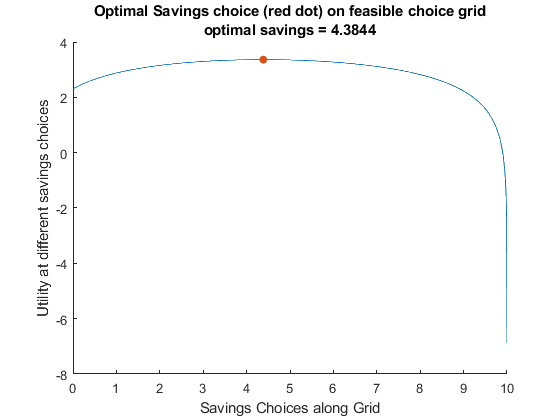

% Plot
figure();
hold on;
plot(save_grid, utility_at_savegrid);
scatter(optimal_savings_choice, max_utility, 'filled');
xlabel('Savings Choices along Grid');
ylabel('Utility at different savings choices');
title({'Optimal Savings choice (red dot) on feasible choice grid';...
      ['optimal savings = ', num2str(optimal_savings_choice)]});